##     OBTENCION DE LA FdT REALIZANDO ESTIMACIONES

Utilizamos un motor DC RF-370C-15370 alimentado con 12 [V]. Para medir las RPM (o bien, rad/s) utilizamos un sensor infrarojo y Arduino UNO, mediante interrupciones y distintos tiempos de muestreo, segun el caso.

###     Estimacion 1:

Tiempo de muestreo: 50 [ms]. Entrada: escalon unitario (infinito). Salida: rad/s.

u = [];     % escalon unitario
rads = [];  % valores de rad/s obtenidos

La herramienta 'iddata' nos permite encapsular las valores medidos de entrada y salida para el sistema (motor) que queremos identificar.

 data1 = iddata(rads, u, 0.05); % salida, entrada, muestreo
 plot(data1);   % graficamos la entrada y la salida en el tiempo

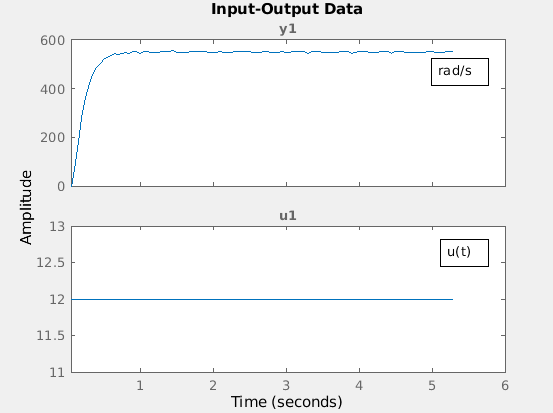

Con la herramienta 'tfest' realizamos una estimacion de la FdT, segun los polos y zeros que indiquemos.

En principio, el sistema parece ser de primer orden:

tf10 = tfest(data1, 1, 0);

Estimacion del 90.9% (muy buena).

Sin embargo, del teorico sabemos que la FdT de un motor DC es de segundo orden, con 2 polos y ningun zero:

tf20 = tfest(data1, 2, 0);

Estimacion del 97.65% (excelente). La FdT calculada es:


$$\frac{8104}{s^2 + 31.83s + 176.6}$$


Podemos comparar los datos ingresados (data1) con la estimacion realizada:

compare(data1, tf20);

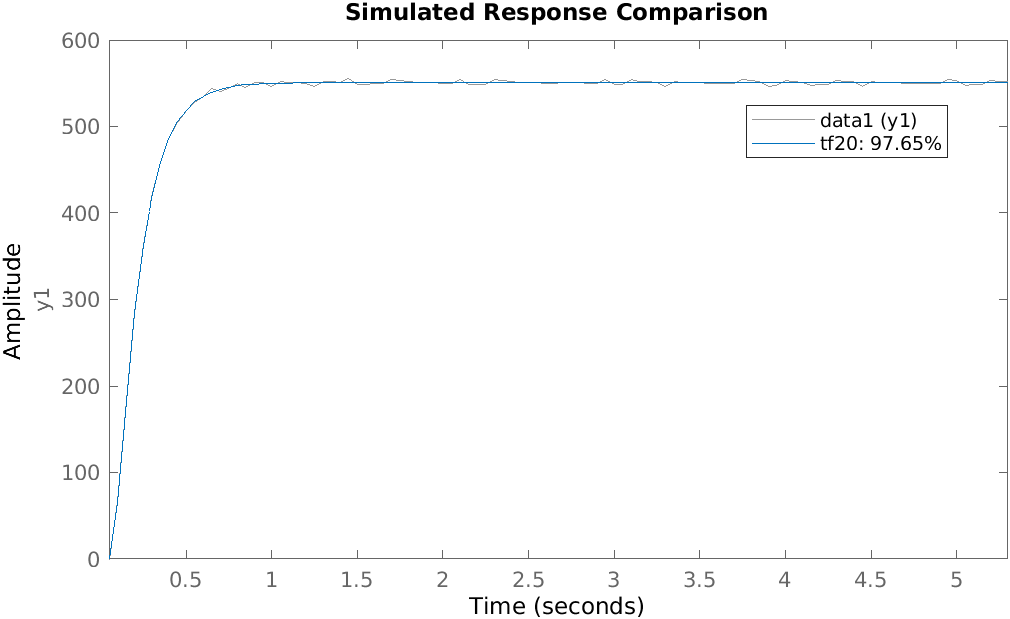

Claramente es muy buena. Incluso, podemos hacer un analisis de residuos y veremos que  hay una alta correlacion

resid(data1, tf20);

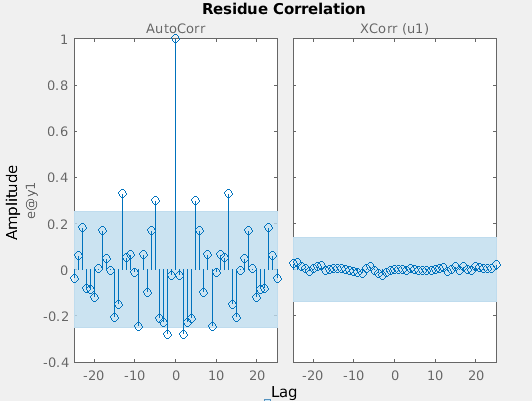

###     Estimacion 2:

Tiempo de muestreo: 50 [ms]. Entrada: pulso unitario (ancho x). Salida: rad/s.

Respecto a la estimacion 1, queremos obtener una FdT teniendo en cuenta cuando el motor se desenergiza y, por lo tanto, la velocidad disminuye. Para ello, ingresamos un pulso de x segundos.

u1 = [];     % escalon unitario
rads1 = [];  % valores de rad/s obtenidos
data2 = iddata(rads1, u1, 0.05);
plot(data2);

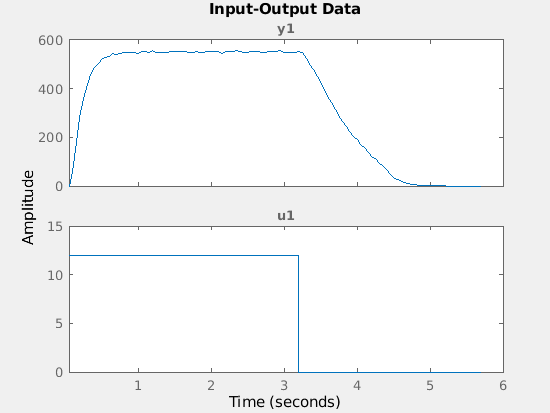

Buscamos la estimacion que mas se aproxime al 100%, variando el numero de poloz y zeros

g10 = tfest(data2, 1, 0);   % est: 78.61%
g20 = tfest(data2, 2, 0);   % est: 94.86%
g21 = tfest(data2, 2, 1);   % est: 84.38%
g31 = tfest(data2, 3, 1);   % est: 86.96%
g32 = tfest(data2, 3, 2);   % est: 83.26%

Nos quedamos con la estimcion g20, que es muy buena y ademas tiene la misma cantidad de polos y zeros que tf20 (calculada en la estimacion 1). Entonces, g20 es


$$\frac{418.2}{s^2 + 6.184 s + 9.174}$$


Si la comparamos con los datos ingresados, el resultado sigue siendo muy bueno

compare(data2, g20);

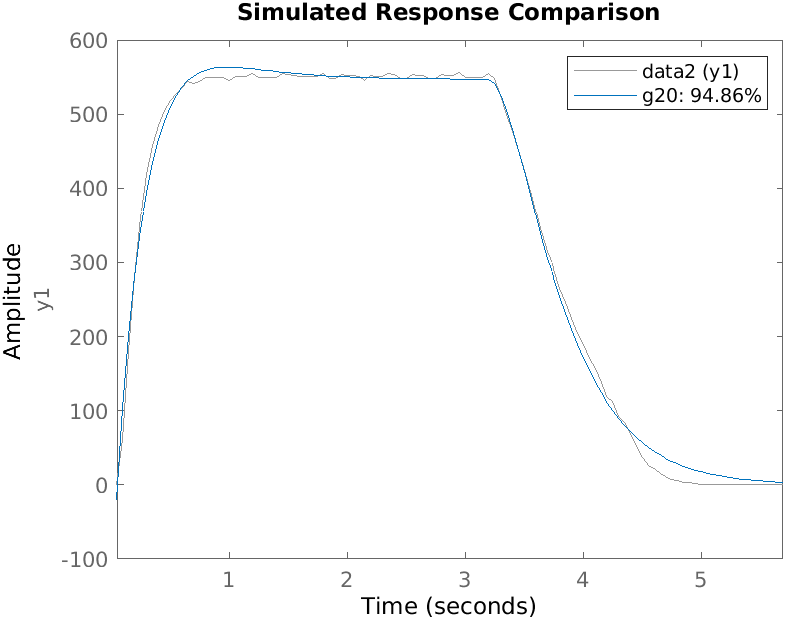

Si bien g20 tiene una estimacion menor que tf20, tenemos una representacion mas amplia de la respuesta del motor. Esto se refleja al comparar estos resultados

compare(data2, g20, tf20);

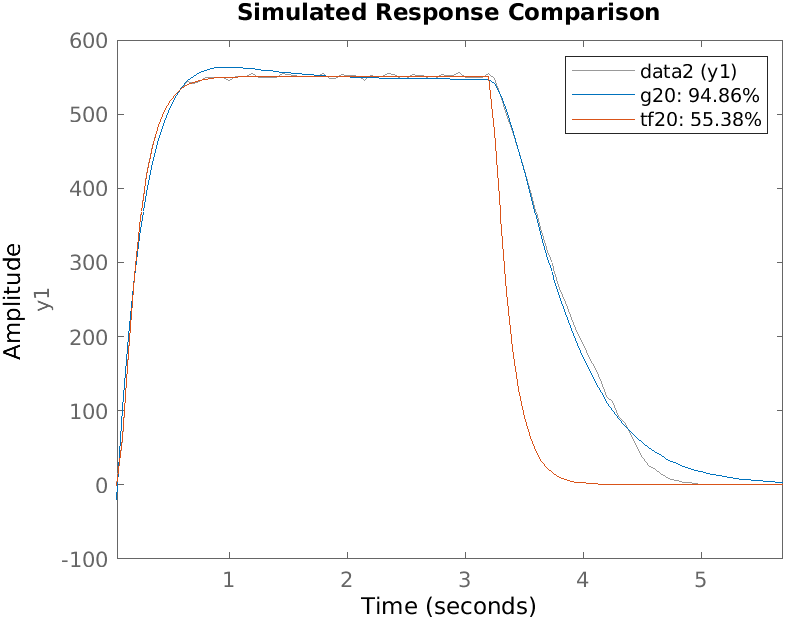

Nuevamente hacemos un analisis de residuos y, si bien la correlacion disminuyo respecto al primer caso, sigue siendo buena.

resid(data2, g20);

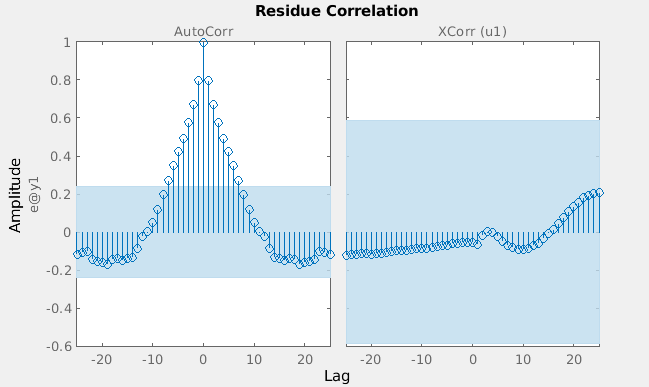

A modo experimental, podemos ver como se aproxima g20 cuando al motor le ingresamos varios pulsos (de ancho x) en el tiempo:

u2 = [];     % escalon unitario
rads2 = [];  % valores de rad/s obtenidos
data3 = iddata(rads2, u2, 0.05);
plot(data3);

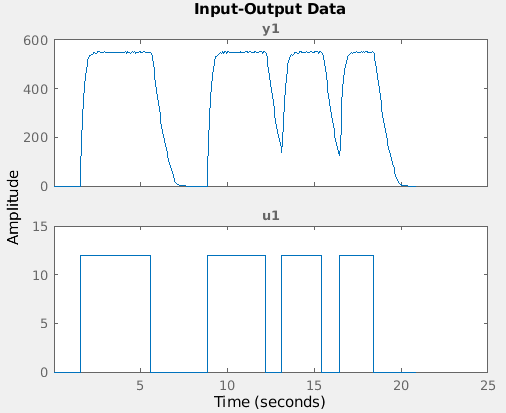

Entonces, comparamos data3 con g20 y la verdad que medio pobre

compare(data3, g20);

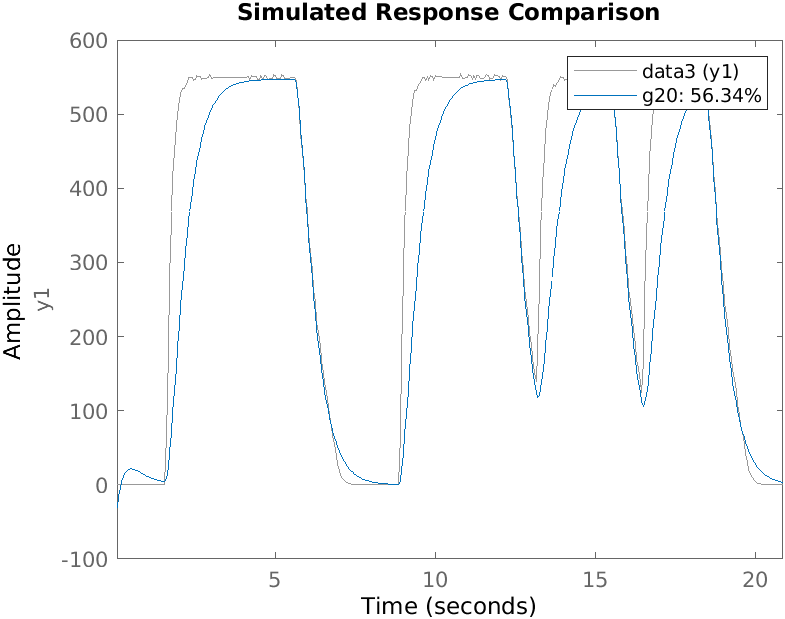

h20 = tfest(data3, 2, 0);   % est: 72.50%
h21 = tfest(data3, 2, 1);   % est: 75.71%
h32 = tfest(data3, 3, 2);   % est: 73.07%
h43 = tfest(data3, 4, 3);   % est: 75.76%

compare(data3, h20)

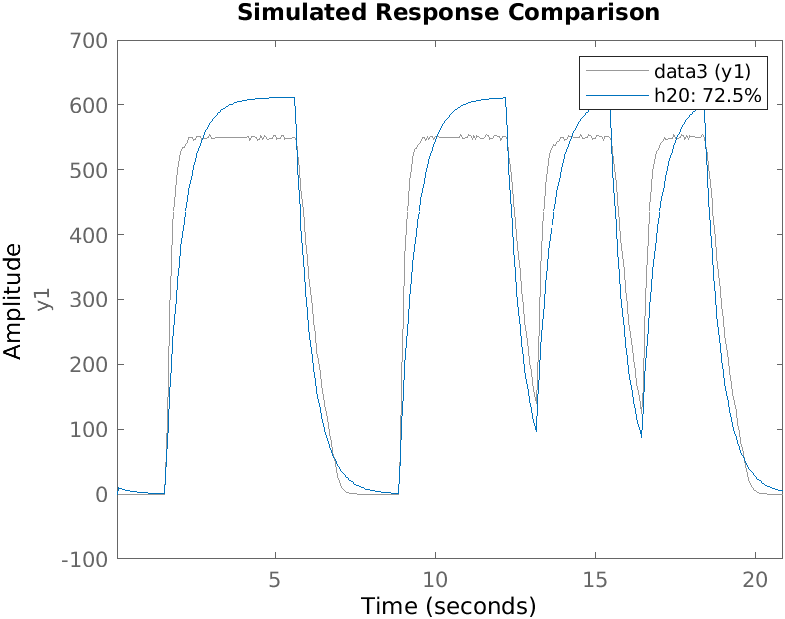


$$\frac{1.463e6}{s^2 + 1.484e4 s + 2.87e4}$$
